fname = 'Fig1h_kymo_all_tracks_global_ringtype_iMedFilt_VerCINI data.csv';
data= importdata(fname);

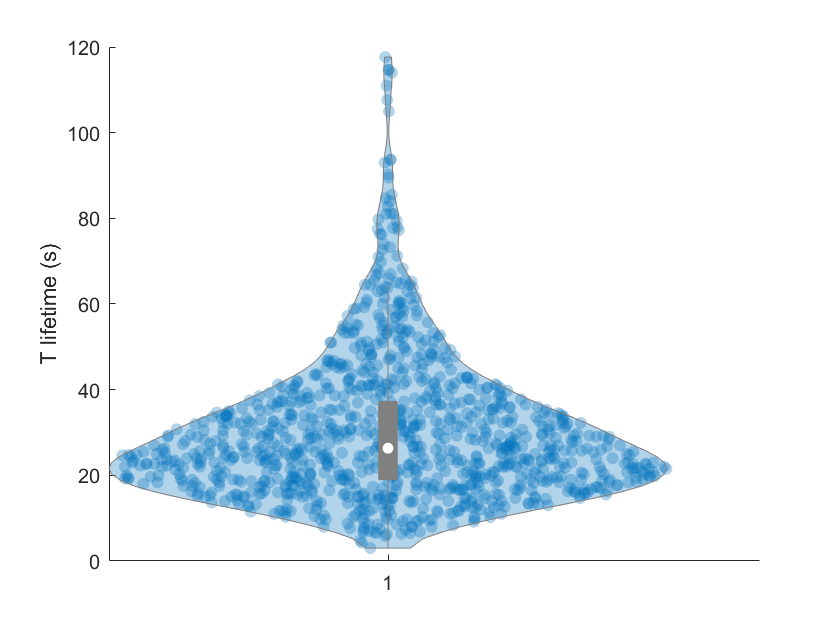

T=abs(data.data(:,2));
S=abs(data.data(:,3));
Diam=data.data(:,7);
isNascent=logical(data.data(:,8));

%keep only the nascent population
T=T(isNascent);%nascent
S=S(isNascent);
Diam=Diam(isNascent);

figure;
violinplot(T);
ylabel('T lifetime (s)');

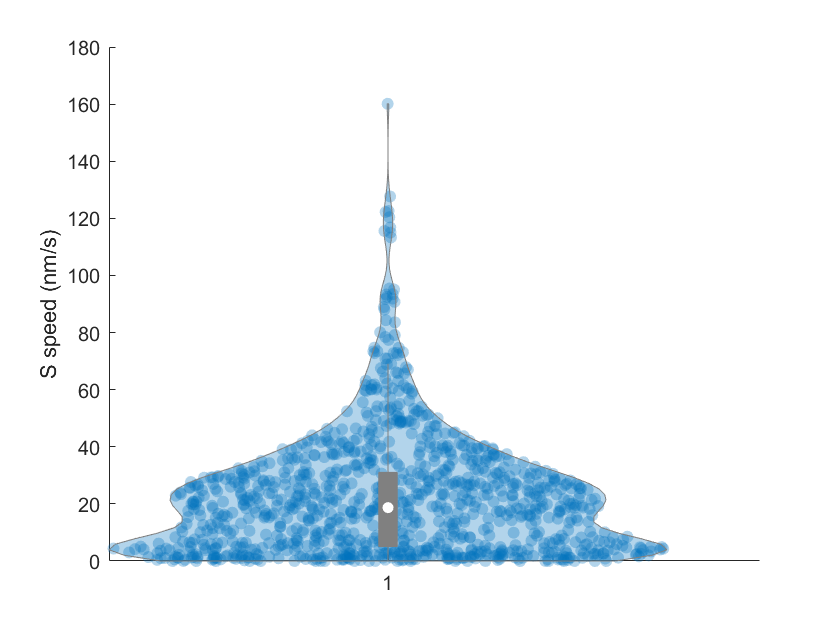


figure;
violinplot(S);
ylabel('S speed (nm/s)')

nascentTracks=table;
nascentTracks.T=T;
nascentTracks.S=S;
nascentTracks.Diam=Diam;
save("nascentTrackData.mat","T","S","Diam","nascentTracks");

nTrackData=numel(T);
TSmat = [T,S];
nTrackKymoAvg=10;
nId=poissrnd(nTrackKymoAvg)

nId = 4

bootId=randi(nTrackData,nId,1)

bootId =    818
   806
   320
   516


trackBootstrapped=TSmat(bootId,:)

trackBootstrapped =    24.0000   27.0833
   18.3333   28.3637
   14.6667   60.5682
   20.0000   26.0000


Above code outlines approach for resampling of the real data to generate ground truth for artificial kymographs

Now test the simulator implementation

nTrackKymoAvg=10;
trackBootstrapped=genSimTrackTS(nascentTracks,nTrackKymoAvg)

bootId =    598
   426
   191
   838
   331
   562
   331
   935
    90
   510


trackBootstrapped = 10×3 table
      T        S        Diam 
    _____    ______    ______

    27.25    13.716     815.1
       53    2.1462    886.72
     16.5    6.8939    902.73
    22.25    35.056    871.93
       36     8.125    934.33
     25.5    17.843    834.19
       36     8.125    934.33
       38      32.5     918.2
        7    39.464    830.45
     18.5    25.473    832.75


%save('exemplarKymoTrack_single.mat','trackBootstrapped');